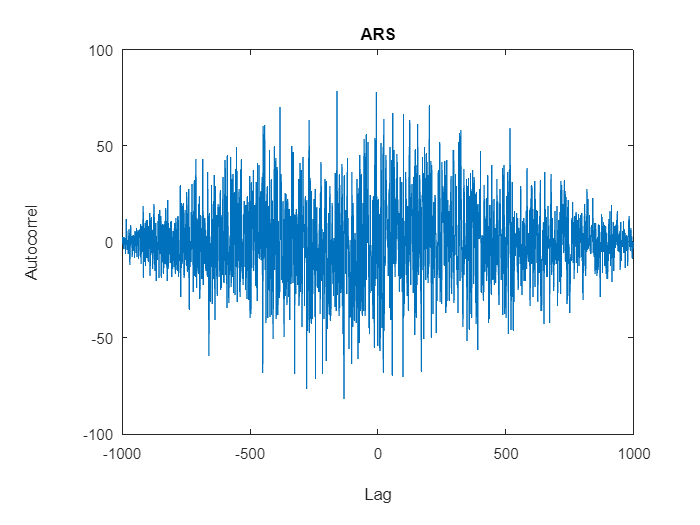

l=1000;
s1 = randn(1,l);
s2=randn(1,l);

auutocorr = xcorr (s1,s2);

lags = -(l-1):(l-1);

figure;
plot(lags,auutocorr);

title("ARS");
xlabel('Lag');
ylabel('Autocorrel');

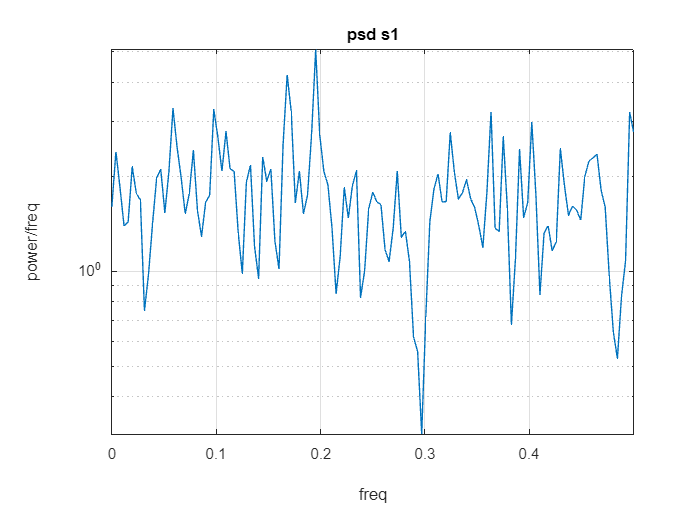


[psd,frequencies]=pwelch(s1,[],[],[],1);

figure;
semilogy(frequencies,psd);
title('psd s1');
xlabel('freq');
ylabel('power/freq');
grid on;